Control de Velocidad  de un Motor 

s= tf('s');
%% declaracion de las constantes 
k = 0.052516664;
B= 6.40115E-05;
L =5.33;
J=4.738e-9;
R= 39.3;
G_s= (k)/((s*L+R)*(s*J+B)+k*k)

G_s =
 
                 0.05252
  --------------------------------------
  2.525e-08 s^2 + 0.0003414 s + 0.005274
 
Continuous-time transfer function.





Ts=0.001;
[num , den] = tfdata(C);
[num , den]= c2dm(num,den,Ts,'zoh');
Control_z= filt(num,den,Ts)

Control_z =
 
  1.038 - 1.028 z^-1
  ------------------
       1 - z^-1
 
Sample time: 0.001 seconds
Discrete-time transfer function.




[num , den] = tfdata(G_s);
[num , den]= c2dm(num,den,Ts,'zoh')

num =          0    0.1416    0.0112


den =     1.0000   -0.9847    0.0000


F_z= filt(num,den,Ts)

F_z =
 
     0.1416 z^-1 + 0.01124 z^-2
  --------------------------------
  1 - 0.9847 z^-1 + 1.347e-06 z^-2
 
Sample time: 0.001 seconds
Discrete-time transfer function.



sistema_z= (Control_z*F_z)/(1+Control_z*F_z)

sistema_z =
 
  0.147 z^-1 - 0.4255 z^-2 + 0.3988 z^-3 - 0.1088 z^-4 - 0.01138 z^-5 + 1.556e-08 z^-6
  -------------------------------------------------------------------------------------
  1 - 3.822 z^-1 + 5.483 z^-2 - 3.51 z^-3 + 0.8607 z^-4 - 0.01138 z^-5 + 1.557e-08 z^-6
 
Sample time: 0.001 seconds
Discrete-time transfer function.



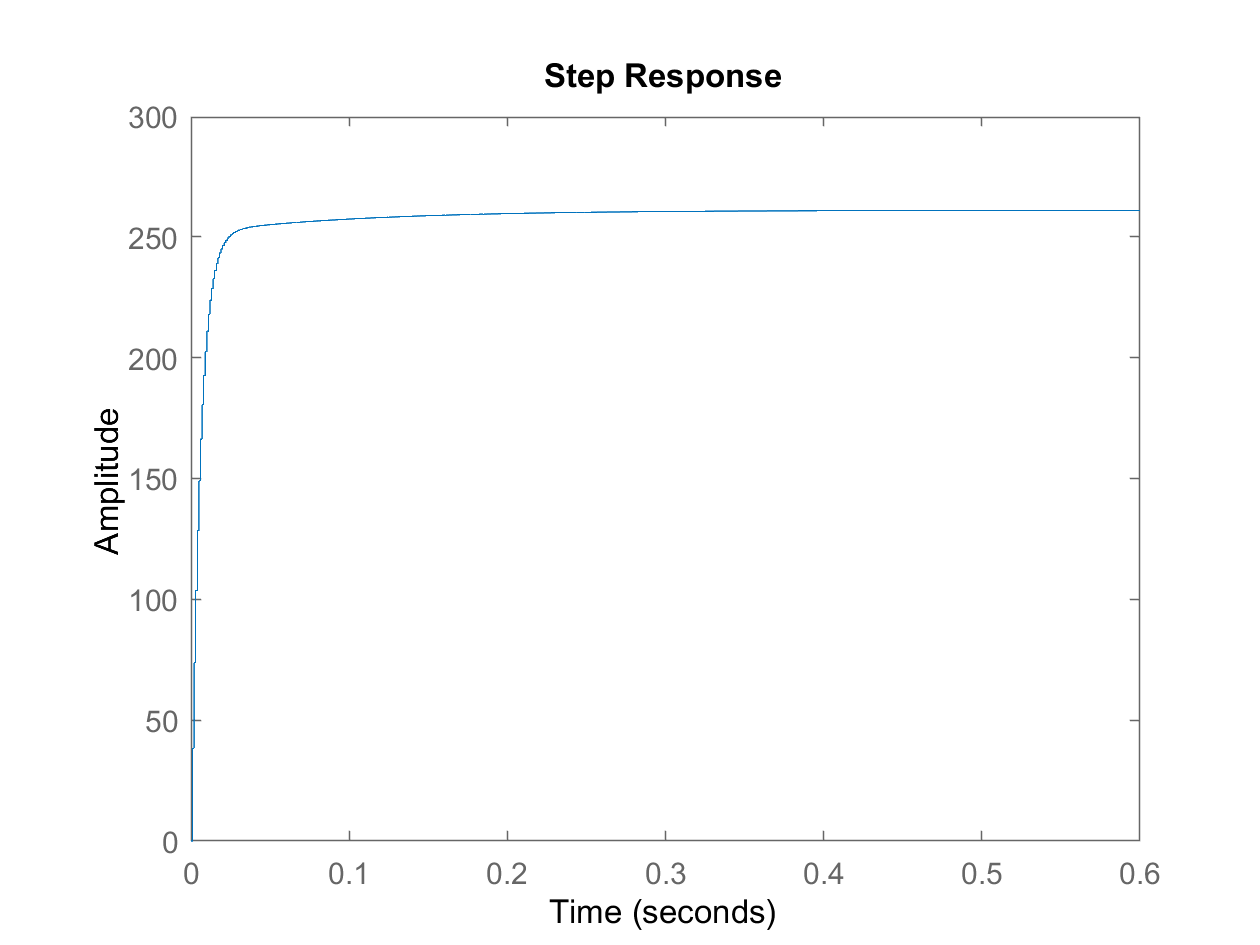


step(sistema_z*261);

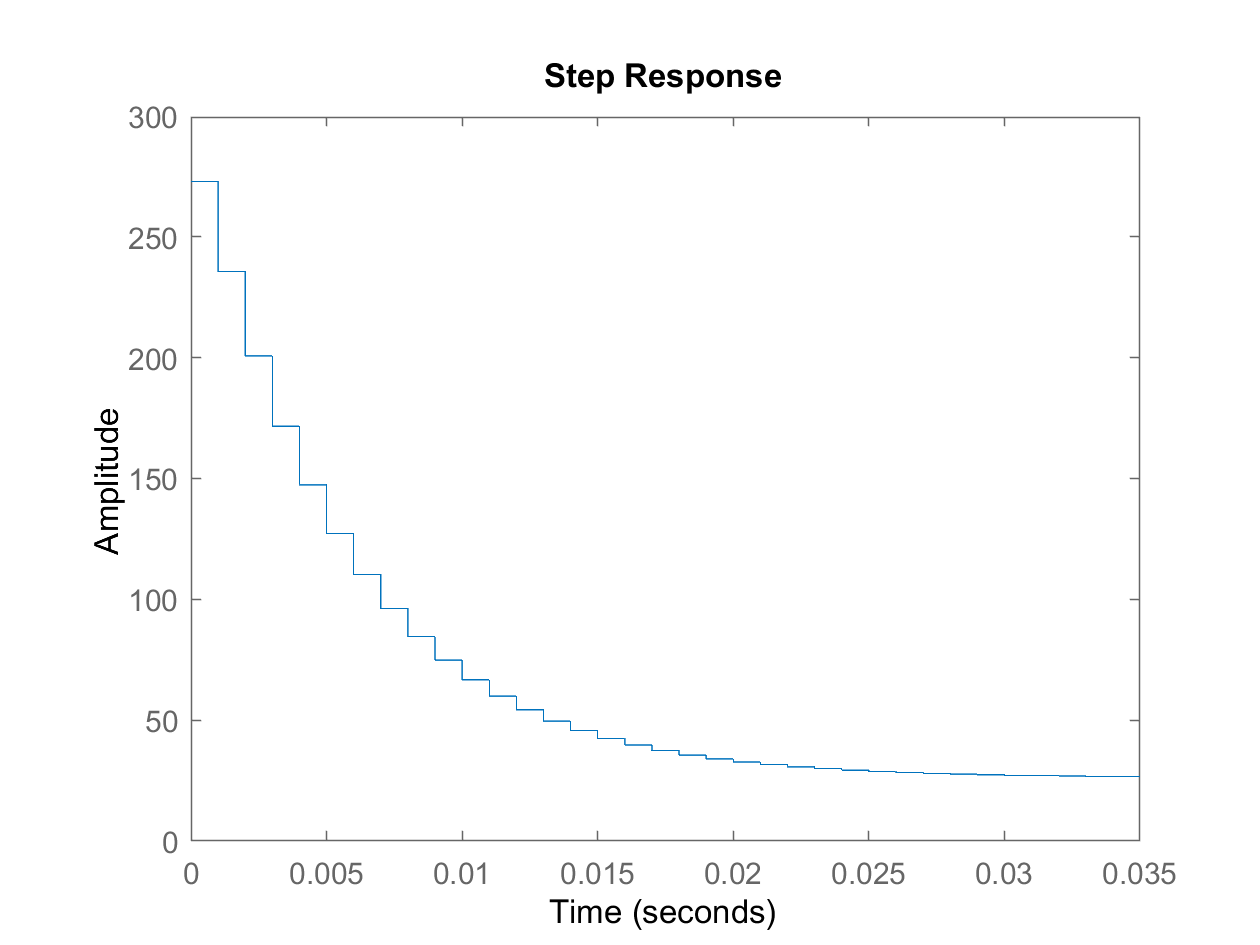

sistema2= Control_z/(1+Control_z*F_z);
step(sistema2*263);

F_z.Denominator{1}

ans =     1.0000   -0.9847    0.0000
